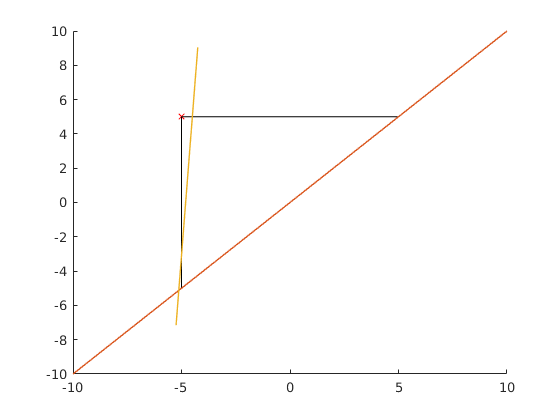

clear
close all

q_min = -10 ;
q_max = 10 ;
q_prec = 0.1 ;

q_pol = [-5 ; 5] ;

alpha = 0.95;
rho = 7.1 ;
W = 1./[1 ; 5] ;

q_old = [ q_min:q_prec:q_max ; q_min:q_prec:q_max ] ;
q_new = q_old + alpha * W .* (q_pol - q_old) ;

hold on
plot(q_pol(1), q_pol(2), 'rx')
line([q_pol(1), q_pol(1)], [q_pol(1), q_pol(2)], 'color', 0*[1,1,1])
line([q_pol(1), q_pol(2)], [q_pol(2), q_pol(2)], 'color', 0*[1,1,1])
plot(q_old(1,:), q_old(2,:), 'linewidth', 1)
plot(q_new(1,:), q_new(2,:), 'linewidth', 1)
hold off

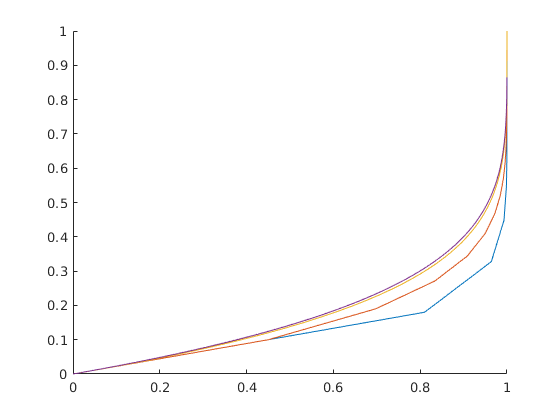

clear
close all

q0 = [ 0 ; 0 ] ;
q1 = [ 1 ; 1 ] ;

hold on
for alpha = [0.9, 0.5, 1e-1, 1e-5]
    path = q0 ;
    for k = 1:1e6
        W = alpha*[0.9 ; 0.2] ;
        path(:,end+1) = path(:,end) + W.*(q1-path(:,end)) ;
    end
    plot(path(1,:), path(2,:))
end
hold off
xlim([min(q0(1), q1(1)), max(q0(1), q1(1))])
ylim([min(q0(2), q1(2)), max(q0(2), q1(2))])